clear;
fol = 'SEREEGA-master';
s = '/';
addpath(fol); 
subfols = dir(fol); 
addpath("SEREEGA-master/docs/");
for idx=7:size(subfols)
    addpath([fol, s, subfols(idx).name]);
end
addpath("SEREEGA-master/leadfield/brainstorm/");
addpath("SEREEGA-master/l" + ...
    "eadfield/nyhead/");
addpath("SEREEGA-master/leadfield/fieldtrip/");
addpath("SEREEGA-master/leadfi" + ...
    "eld/hartmut/");
addpath("SEREEGA-master/leadfield/pha/");
subfols = dir("SEREEGA-master/signal"); 
for idx=4:size(subfols)
    addpath(['SEREEGA-master/signal/', subfols(idx).name]);
end

## **Trial all signal types **

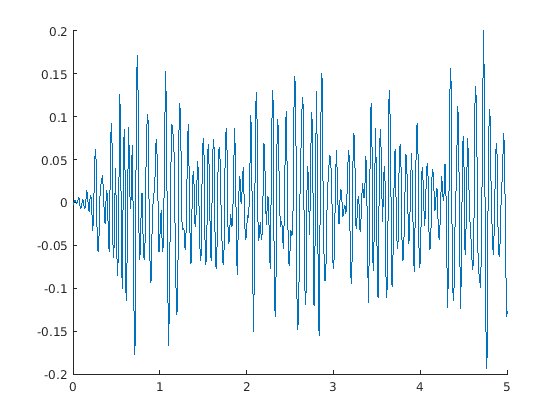

trial = struct();
trial.n = 1; % the number of epochs to simulate
totlen = 5;  %seconds
trial.srate = 200;        % their sampling rate in Hz
trial.length = totlen*1e03;  % their length in ms
background_signal  = struct( ...
        'type', 'ersp', ...
        'frequency', [8 10 15 28], ...
        'amplitude', .2, ...
        'modulation', 'none');

background_signal = utl_check_class(background_signal);

background_signal = utl_check_class(background_signal);

plot_signal_fromclass(background_signal, trial);

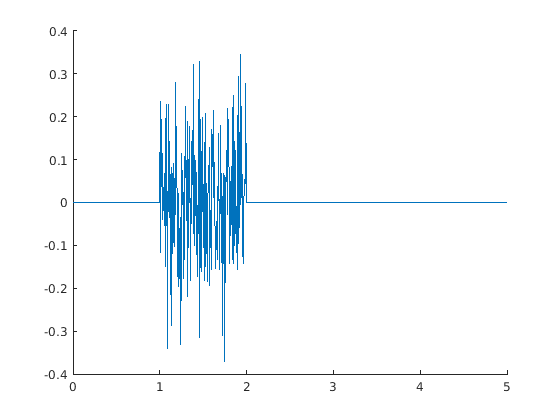

ans =   Figure (8: Data signal) with properties:

      Number: 8
        Name: 'Data signal'
       Color: [1 1 1]
    Position: [680 485 560 420]
       Units: 'pixels'

  Show all properties


noiseamp = 0.5;
gauss_noise = struct( ...
        'type', 'noise', ...
        'color', 'white', ...
        'amplitude', noiseamp);
gauss_noise = utl_check_class(gauss_noise);
noisestart = 1;
noiseend = 2;
tempsig = generate_signal_fromclass(gauss_noise, trial);
tempsig(1:noisestart*trial.srate ) = 0;
tempsig(noiseend*trial.srate-1:end ) = 0;
noise_data = struct();
noise_data.data = tempsig;
noise_data.index = {'e', ':'};
noise_data.amplitude = 1.0;
noise_data.amplitudeType = 'relative';
noise_data = utl_check_class(noise_data, 'type', 'data');
plot_signal_fromclass(noise_data , trial)

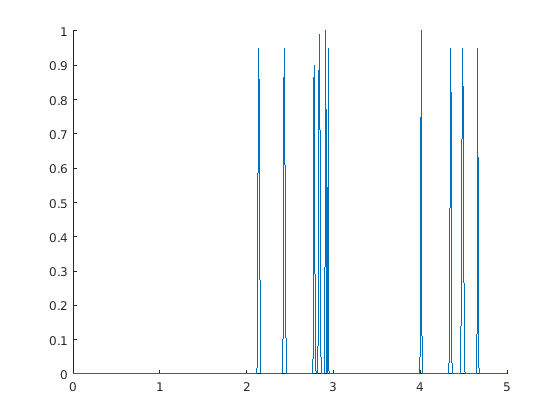

ans =   Figure (9: ERP signal) with properties:

      Number: 9
        Name: 'ERP signal'
       Color: [1 1 1]
    Position: [680 485 560 420]
       Units: 'pixels'

  Show all properties


spikestart = 2;
spikeend = 3;
len = spikeend-spikestart; 
minspikes = 6*len; 
maxspikes = 14*len; 
spikedata = erp_get_class_random([minspikes:maxspikes], ...  %number of spikes range
                                 [spikestart*1e03:spikeend*1e03, 4000:5000], ... %given timepoints only
                                 [10:50], ...                 %width of spike range
		                         [0.9:0.05:1]);  %amplitude range
plot_signal_fromclass(spikedata , trial)

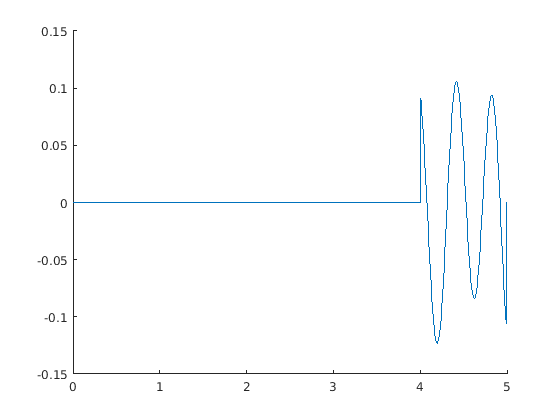

slowstart = 4;  
slowend = 5; 
slowsignal  = struct( ...
        'type', 'ersp', ...
        'frequency', [1 2 2.5 3], ...
        'amplitude', .2, ...
        'modulation', 'none');

slowsignal = utl_check_class(slowsignal);

tempsig = generate_signal_fromclass(slowsignal, trial);
tempsig(1:slowstart*trial.srate ) = 0;
tempsig(slowend*trial.srate-1:end ) = 0;
slowsignal = struct();
slowsignal.data = tempsig;
slowsignal.index = {'e', ':'};
slowsignal.amplitude = 1.0;
slowsignal.amplitudeType = 'relative';
slowsignal = utl_check_class(slowsignal, 'type', 'data');


plot_signal_fromclass(slowsignal, trial);

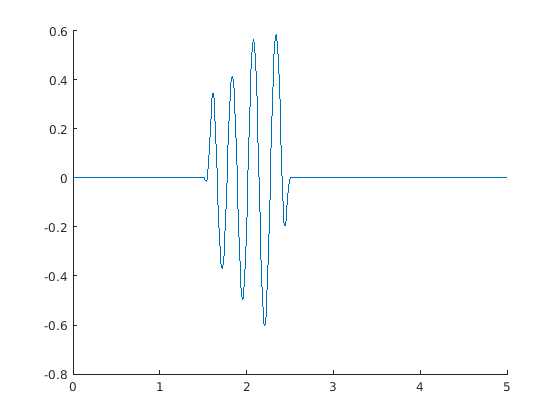

%data_v2 - 100% noise at random
szon = 10; 
szoff = 50; 
len= szoff - szon; 
minspikes = round(2.5*len); 
maxspikes = 4  * len; 
sz_spikes = erp_get_class_random([minspikes:maxspikes], ...  %number of spikes range
                                 [szon*1e03:szoff*1e03], ... %seizure timepoints only
                                 [20:70], ...                 %width of spike range
		                         [-1:0.05:-0.95, 0.95:0.05:1]);  %amplitude range
rng("shuffle")

sz_sharps = erp_get_class_random([maxspikes:maxspikes],...
                                  [szon*1e03:szoff*1e03],...
                                  [70:200], ...
		                         [-1:0.05:-0.95, 0.95:0.05:1]);
ersp = struct( ...
        'type', 'ersp', ...
        'frequency', [3 3.5 4 5], ...
        'amplitude', 1.0, ...
        'modulation', 'none');
ersp.modulation = 'burst';
ersp.modLatency = 2*1000;      % centre of the burst, in ms
ersp.modWidth = 1000;        % width (half duration) of the burst, in ms
ersp.modTaper = 0.25;        % taper of the burst

ersp = utl_check_class(ersp);

plot_signal_fromclass(ersp, trial ...
    );